**Classify Breast Tumors from Ultrasound Images Using Radiomics Features**

This example shows how to use radiomics features to classify breast tumors as benign or malignant from breast ultrasound images.

Radiomics extracts a large number of features from medical images related to the shape, intensity distribution, and texture of the specified region of interest (ROI). The extracted radiomics features contain useful information of the medical image that you can use in a classification application for automated diagnosis. This example extracts radiomics features from the tumor regions of breast ultrasound images and uses these features in a deep learning network to classify whether the tumor is benign or malignant.

**ABOUT THE DATA SET**

this example uses the **breast ultrasound images (busi) data set** [1]. the busi data set contains 2-d ultrasound images stored in the png file format. the total size of the data set is 196 mb. the data set contains 133 normal scans that have no tumors, 437 scans with benign tumors, and 210 scans with malignant tumors. *each ultrasound image has a corresponding tumor mask image and a label of normal, benign, or malignant*; these labels have been reviewed by clinical radiologists [1]. the normal scans do not have any tumor regions in their corresponding tumor mask images. thus, this example uses images from only the tumor groups.

SET UP:

% clean slate
clear;
close all;
clc;
if isMATLABReleaseOlderThan('R2024a')
    cont=questdlg("This demo must be run in R2024a or later","Version Too Old!","STOP","Continue","STOP");
    if ~strcmp(cont,"Continue")
        return 
    end
end

% Train Option;NOTE:Training lives takes about 10 minutes(total)
trainLive=false;
% Tune option;NOTE:Tuning model takes about 12 minutes
tuneModel=false;
%Save option:
saveIt=true;

% FOR NAMING MATFILE:
% NOTE:The doc examples uses "internal pairing"(my phrase) to discard any
% featues that are highly correlated with another feature--ti avoid
% unnecessary compute.I propose that it is also worthwhile to pare by
% comparing feature,correlation with the target classification.In this,demo
% we will do both

if true 
    paringOption={"Malignancy","Internal"};%In this order
    paringAbbrev="MI";
else
    paringOption="None";
    paringAbbrev="None";
end

featuresAbbrev="SIT";
% NOTE: The radiomics function computers SHAPE,INTENSITY,and TEXTURE
% featues on masked regions,we can use all or any subset of those
% features.In this demo,we will use all.
includedFeatures={'shape',"intensity",'texture'};

 if trainLive
     disp("Training LIVE...")
 else
     disp("Recalling PREVIOUS training...");
 end

Recalling PREVIOUS training...


 %
  saveRecallName="Radiomics"+featuresAbbrev+"_"+paringAbbrev

saveRecallName = "RadiomicsSIT_MI"

**DOWNLOAD DATA SET**

Download and unzip the data,if necessary.

 data/Dataset_BUST.zip

filepath=fullfile(userpath,"Examples");
if ~exist(fullfile(filepath,"Dataset_BUSI_with_GT"),"dir")
    disp("Downloading/Installing Data.")
    zipFile="C:\Users\hp\OneDrive\Desktop\Medical Image Analysis\Dataset_BUSI_with_GT.zip";
    unzip(zipFile,filepath)
else
    disp("Data already exist.")
end

Data already exist.


**LOAD AND PREPARE DATA SET:**

Prepare the data for training by performing these tasks.

1.Label each image as normal,benign,or malignant,based on the name of its folder.

2. Separate the uletrasound and mask images.

3. Retain images from only the rumour group.

4. Create a variable to store labels.

Create a variable imageDir that points to the folder containing the downloaded and the unzipped data set.Create an image datastore to read and manage the ultrasound image data.Label each image as normal,benign,or malignant,based onthe name of its folder.

imageDir=fullfile(filepath,"Dataset_BUSI_with_GT");
fullImds=imageDatastore(imageDir,IncludeSubfolders=true,LabelSource="foldernames");
imdsWithTumors=subset(fullImds,~contains(fullImds.Files,"normal")); % Find isn't necessary!

Create a subset of the tumor-image datastore containing only the ultrasound images by selecting only files whose names do not contain "mask".

imageImds=subset(imdsWithTumors,~contains(imdsWithTumors.Files,"mask"));

Create a subset of the tumor-image datastore containig only the tumor mask images corresponding to the ultrasound images by selecting all files whose names contain "mask.png".(Note that there are some dulpicate maks...mask_1.png.mask_2.png etc)

maskImds=subset(imdsWithTumors, contains(imdsWithTumors.Files,"mask.png"));

Create a vector named labels from the labels of the ultrasound image datastore.The ***removecats*** function unused categories array.

labels=imageImds.Labels;
labels=removecats(labels); % Removes (unused) "normal category
unique(labels)

ans = 2×1 categorical array
     benign 
     malignant 


** VEIW SAMPLE DATA:**

Veiw sample ultrasound that contains benign and malignant tumors,with the tumor masks on the images.

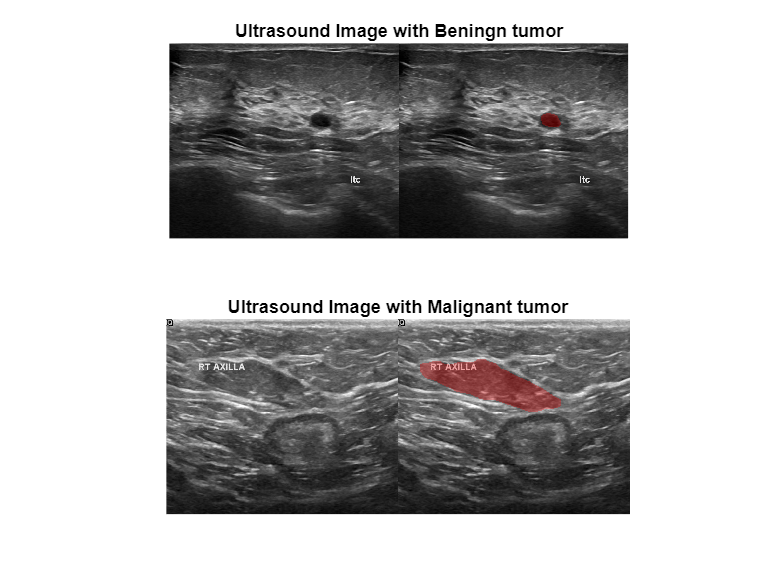

benignIndices=find(maskImds.Labels=="benign");%437
thisBenignIndex=58;
benignImage=readimage(imageImds,benignIndices(thisBenignIndex));
benignMask=readimage(maskImds,benignIndices(thisBenignIndex));
benignVis=labeloverlay(benignImage,benignMask,Transparency=0.7,Colormap=[1 0 0]);
%
malignantIndices=find(maskImds.Labels=="malignant"); %210
thisMalignantIndex=35;
malignantImage=readimage(imageImds,malignantIndices(thisMalignantIndex));
malignantMask=readimage(maskImds,malignantIndices(thisMalignantIndex));
malignantVis=labeloverlay(malignantImage,malignantMask,Transparency=0.7,Colormap=[1 0 0]);

% Visualize
figure
tiledlayout(2,1)
nexttile
imshowpair(benignImage,benignVis,"montage");
title("Ultrasound Image with Beningn tumor")
nexttile
imshowpair(malignantImage,malignantVis,"montage");
title("Ultrasound Image with Malignant tumor")

**CREATE TRAINING AND TEST DATA SETS**

Split the data into 70 percent training data and 30 percent test data using holdout validation.

numImages=length(imageImds.Files);
idx=1:numImages;
rng("default")
fraction=0.3

fraction = 0.3000

dataPartition=cvpartition(numImages,"Holdout",fraction); % Partition data for cross-validation
idxTrain=training(dataPartition);
idxTest=test(dataPartition);

Create separate vectors for the labels of the training and test data.

labelsTrain=labels(idxTrain);
labelsTest=labels(idxTest);
disp("You have"+numel(labelsTrain)+"training images"+"("+numel(unique(labelsTrain))+"classes"+")"+newline+"...and"+numel(labelsTest)+"test images"+"("+numel(unique(labelsTest))+"classes"+")")

You have453training images(2classes)
...and194test images(2classes)


**COMPUTE RADIOMICS FEATURES FOR TRAINING DATA**

The shape of breast tumors in a medical image is very informative for the purpose of classifying breast tumors as benign or malignant.Thus,in this example,you compute the **shape-,intensity-,and texture-related radiomics features** from the tumor regions of the breast ultrasound images.

Create an empty table named radiomicsFeaturesTrain.

%
radiomicsFeaturesTrain=table;
[S,I,T]=deal([]);
trainingIndices=find(idxTrain);
nTrainingImages=numel(trainingIndices);

% Training Live takes about 8-10 minutes...
% Define paths and filenames
if trainLive
    tic;
    t=1;
    for ii=1:nTrainingImages % idx(idxTrain)
        disp("Processing image"+ii+"of"+nTrainingImages)
        idx=trainingIndices(ii);
        img=readimage(imageImds,idx);
        img=im2gray(img);
        %
        img=cat(3,img,zeros([size(img) 2],class(img)));
        volGeometry=medicalref3d(size(img));
        data=medicalVolume(img,volGeometry);
        data.Voxels=squeeze(data.Voxels);

        masking=readimage(maskImds,idx);
        masking=im2uint16(masking);
        masking=cat(3,masking,zeros([size(masking) 2],class(masking)));
        volGeometry=medicalVolume(masking,volGeometry);
        roiData=medicalVolume(masking,volGeometry);
        roiData.Voxels=squeeze(roiData.Voxels);

        masking=readimage(maskImds,idx);
        masking=im2uint8(masking);
        masking=cat(3,masking,zeros([size(masking) 2],class(masking)));
        volGeometry=medicalref3d(size(masking));
        roiData=medicalVolume(masking,volGeometry);
        roiData.Voxels=squeeze(roiData.Voxels);
        %
        R=radiomics(data,roiData);
        %
        thisImageFeatures=[];
        if ismember("shape",includedFeatures)
            S=shapeFeatures(R,SubType="2D");
            S=removevars(S,"LabelID");
            thisImageFeatures=[thisImageFeatures,S];
        end
        if ismember("intensity",includedFeatures)
            I=intensityFeatures(R,SubType="2D");
            I=removevars(I,"LabelID");
            thisImageFeatures=[thisImageFeatures,I];
        end
        if ismember("texture",includedFeatures)
            T=textureFeatures(R,SubType="2D");
            T=removevars(T,"LabelID")
            thisImageFeatures=[thisImageFeatures,T];
        end
        radiomicsFeaturesTrain(ii,:)=thisImageFeatures;
        t=t+1;
    end
    saveIt=true;
    if saveIt
        save(fullfile(imageDir,saveRecallName+"Train.mat"),"R","S","T","I","radiomicsFeaturesTrain","thisImageFeatures","labelsTrain");
    end
    tTraining=toc;
else
    disp("Loading pretrained features")
    load(fullfile(imageDir,saveRecallName+"Train.mat"),"R","S","T","I","radiomicsFeaturesTrain","thisImageFeatures","labelsTrain")
end

Loading pretrained features


For each ultrasound image in the training data,import the ultrasound image DICOM file and the corresponding tumor mask DICOM file as medicalVolume objects.Create a radiomics object using the ultrasound medical volume as the data and the tumor mask medical volume as the ROI labels.**Compute the shape features** of the radiomics object,remove the variable labelID,and append the features to radiomicsFeaturesTrain.The feature computation may take a long time depending on your system configuration.

Convert the table radiomicsFeaturesTrain to an array.Save the features name in the variable featureName.

radiomicsFeaturesTrain=table2array(radiomicsFeaturesTrain);
featureNames=thisImageFeatures.Properties.VariableNames;

**PARE INFORMATION: Remove Redundant and Unuseful Radiomics Features**

Compute the number of features.

nFeatures=numel(featureNames);
disp("Initially,there are"+nFeatures+"features in the dataset.")

Initially,there are208features in the dataset.


%
% Create a logical vector that corresponds to the the labels of the
% training data,representing benign labels with the value false and
% malignant labels with the value true.
labelsTrainLogical=labelsTrain=="malignant";
[selectedFeatures,radiomicsFeaturesTrain,featureNames]= pareSelection(radiomicsFeaturesTrain,paringOption,featureNames,labelsTrainLogical);

Malignancy pairing: 208 → 29 features


If the magnitude of the correlation coffecient between two radiomics features is features is greater than or equal to 0.975*,the features are redundant with one another .And if the correlation coefficient between "malignancy" and a radiomics features is<0.3*,the features is not useful.Remove each redundant from the training and test data,as well as from the list of feature names.

****User-configurable***

disp(sort(featureNames)')

    {'AreaDensityAABB_2D'       }
    {'AreaDensityAEE_2D'        }
    {'AreaDensityConvexHull2D'  }
    {'Asphericity2D'            }
    {'CentreOfMassShift2D'      }
    {'Compactness1_2D'          }
    {'Compactness2_2D'          }
    {'Elongation2D'             }
    {'Flatness2D'               }
    {'GlobalIntensityPeak2D'    }
    {'IntegratedIntensity2D'    }
    {'IntensityKurtosis2D'      }
    {'IntensitySkewness2D'      }
    {'IntensityVariance2D'      }
    {'LeastAxisLength2D'        }
    {'LocalIntensityPeak2D'     }
    {'MajorAxisLength2D'        }
    {'Maximum3dDiameter2D'      }
    {'MeanIntensity2D'          }
    {'MinorAxisLength2D'        }
    {'SphericalDisproportion2D' }
    {'Sphericity2D'             }
    {'SurfaceAreaMesh2D'        }
    {'SurfaceVolumeRatio2D'     }
    {'VolumeDensityAABB_2D'     }
    {'VolumeDensityAEE_2D'      }
    {'VolumeDensityConvexHull2D'}
    {'VolumeMesh2D'             }
    {'VolumeVoxelCount2D'       }



**VISUALIZE RADIOMICS FEATURES:**

Compute the number of features after feature selection.

Visualize each selected feature for the training data alongside their labels.The first bar in the visualization shows the ground truth classification on the training data,with the benign tumors indicated in blue and malignant tumors indicated in yellow.The  rest of the bars show each of the selected features.Note that although the colormap of each feature is different,the trendof each feature changes where the malignancy changes.For example,for the VolumeDensityConvexHull2D feature,the bottom portion of the bar corresponding to malignant tumors is more blue than the upper poryion corresponding to the benign tumors.

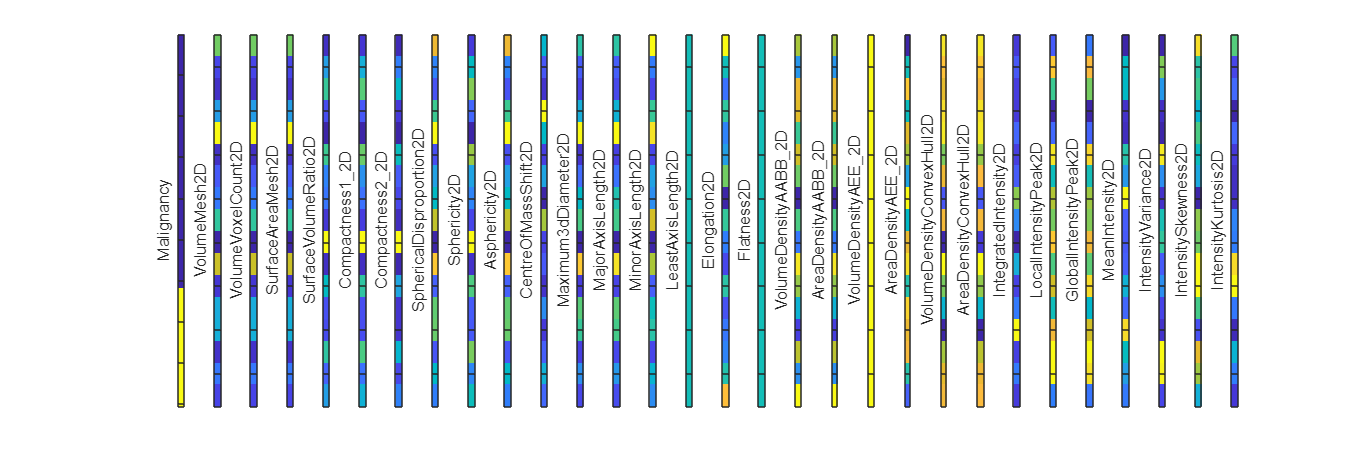

if nnz(selectedFeatures)<50
    figure(Position=[0 0 1500 500])
    tiledlayout(1,nnz(selectedFeatures)+1,TileSpacing="compact")
    colormap(parula)
    nexttile
    imagesc(labelsTrainLogical)
    xticklabels({})
    yticklabels({})
    ylabel("Malignancy",Interpreter="none")
    for ii=1:nnz(selectedFeatures)
        nexttile
        imagesc(radiomicsFeaturesTrain(:,ii))
        xticklabels({})
        yticklabels({})
        ylabel(featureNames{ii},Interpreter="none")
    end
end

**TRAIN DEEP LEARNING NETWORK**

**Fitcauto:**

Note:This example uses the deep learning classification neutral network model and hyperparametres automatically determined by the fitcauto function to minimize validation loss.The functionautomatically selects a classification model with optimized hyperparameters!

%% Train Deep Learning Model with Radiomics Features (Corrected)
% This section:
% 1. Handles Inf/NaN values 
% 2. Ensures feature-label size matching
% 3. Safely trains with fitcauto

% -------------------------------------------------------------------------
% STEP 1: Verify and Clean Feature Matrix
% -------------------------------------------------------------------------

% Convert to double precision if needed
if ~isa(radiomicsFeaturesTrain, 'double')
    radiomicsFeaturesTrain = double(radiomicsFeaturesTrain);
end

% Check for Inf/NaN values
if any(isinf(radiomicsFeaturesTrain(:))) || any(isnan(radiomicsFeaturesTrain(:)))
    fprintf('Cleaning data: Found %d Inf and %d NaN values\n', ...
            sum(isinf(radiomicsFeaturesTrain(:))), ...
            sum(isnan(radiomicsFeaturesTrain(:))));
    
    % Replace Inf with NaN first
    radiomicsFeaturesTrain(isinf(radiomicsFeaturesTrain)) = NaN;
    
    % Impute NaN with column medians (robust to outliers)
    for col = 1:size(radiomicsFeaturesTrain, 2)
        col_data = radiomicsFeaturesTrain(:, col);
        nan_mask = isnan(col_data);
        if any(nan_mask)
            col_median = median(col_data(~nan_mask), 'omitnan');
            radiomicsFeaturesTrain(nan_mask, col) = col_median;
        end
    end
end

Cleaning data: Found 17 Inf and 0 NaN values



% Remove zero-variance features
var_threshold = 1e-6;
feature_vars = var(radiomicsFeaturesTrain);
low_var_features = feature_vars < var_threshold;

if any(low_var_features)
    fprintf('Removing %d low-variance features\n', sum(low_var_features));
    radiomicsFeaturesTrain(:, low_var_features) = [];
    featureNames(low_var_features) = [];
end

Removing 3 low-variance features


Training NEW model with hyperparameter optimization using fitcecoc.


|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale | PolynomialOr-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | der          |
|====================================================================================================================|
|    1 | Best   |           0 |      3.1616 |           0 |           0 |            1 |       417.86 |            3 |
|    2 | Accept |           0 |      0.6467 |           0 |           0 |            1 |    0.0042008 |            2 |
|    3 | Accept |           0 |      0.2728 |           0 |           0 |            1 |     0.010213 |            4 |
|    4 | Accept |           0 |     0.21019 |           0 |           0 |            1 |       4.8943 |            4 |
|    5 | Accept |           0 |     0.42529 |   

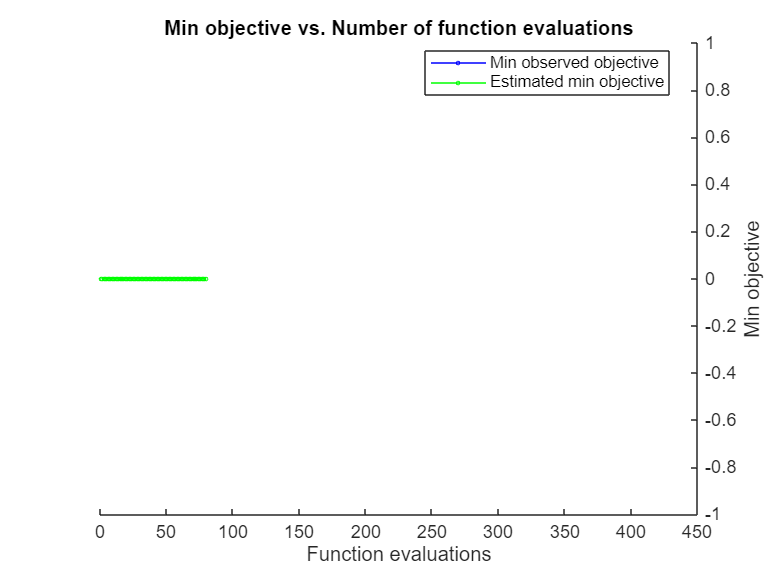

filename = "fitcecocOptimResults" + featuresAbbrev + "_" + paringAbbrev + ".mat";
tuneModel=true;
if tuneModel
    disp("Training NEW model with hyperparameter optimization using fitcecoc.");
    
    radiomicsFeaturesTrain = double(radiomicsFeaturesTrain);
    labelsTrain = categorical(cellstr(labelsTrain(1:17)));

    % Verify sizes match
    assert(size(radiomicsFeaturesTrain,1) == numel(labelsTrain), ...
        'Feature/label size mismatch');
    
    % Optimization options
    opts = struct;
    opts.AcquisitionFunctionName = 'expected-improvement-plus';
    opts.ShowPlots = true;
    opts.Verbose = 1;
    opts.MaxObjectiveEvaluations = 80; % Adjust as needed
    
    tic;
    % Train model with optimization
    Mdl = fitcecoc(radiomicsFeaturesTrain, labelsTrain, ...
        'OptimizeHyperparameters', {'BoxConstraint','KernelScale','PolynomialOrder'}, ...
        'HyperparameterOptimizationOptions', opts);

xlim([0 450])
ylim([-1.00 1.00])
    tTune = toc;
    
    save(filename, 'Mdl');
    
else
    if isfile(filename)
        load(filename, 'Mdl');
    else
        error("Model file '%s' not found. Set tuneModel to true to train the model first.", filename);
    end
end



disp(Mdl);

  ClassificationECOC
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: benign
                       ScoreTransform: 'none'
                       BinaryLearners: {[]}
                           CodingName: 'onevsone'
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods



**CLASSIFY *****TEST***** DATA USING TRAINED DEEP LEARNING NETWORK **


  %% Classify Test Data Using Trained Deep Learning Network
% Initialize storage
radiomicsFeaturesTest = [];
labelstest = [];
testingIndices = find(idxTest);  
% Number of test images
nTestingImages = numel(testingIndices);
% Start timer
tic
wb = waitbar(0, 'Processing Test Images...');
 
    thisImageFeatures = []; 
    if ismember("shape",string(includedFeatures))
        S = shapeFeatures(R, SubType="2D");
        S = removevars(S,"LabelID");
        thisImageFeatures = [thisImageFeatures,S];
    end
    if ismember("intensity", string(includedFeatures))
        I = intensityFeatures(R, 'SubType', "2D");
        I = removevars(I, "LabelID");
        thisImageFeatures = [thisImageFeatures, I];
    end
    if ismember("texture", string(includedFeatures))
        T = textureFeatures(R, 'SubType', "2D");
        T = removevars(T, "LabelID");
        thisImageFeatures = [thisImageFeatures, T];
    end

    radiomicsFeaturesTest(ii, :) = table2array(thisImageFeatures);
    % Replace your waitbar code with simple text updates:
for ii = 1:nTestingImages
    if mod(ii,10) == 0  % Update every 10 images
        fprintf('Processing image %d/%d (%.1f%%)\n', ii, nTestingImages, 100*ii/nTestingImages);
    end
    % ... rest of your processing ...
end

Processing image 10/194 (5.2%)
Processing image 20/194 (10.3%)
Processing image 30/194 (15.5%)
Processing image 40/194 (20.6%)
Processing image 50/194 (25.8%)
Processing image 60/194 (30.9%)
Processing image 70/194 (36.1%)
Processing image 80/194 (41.2%)
Processing image 90/194 (46.4%)
Processing image 100/194 (51.5%)
Processing image 110/194 (56.7%)
Processing image 120/194 (61.9%)
Processing image 130/194 (67.0%)
Processing image 140/194 (72.2%)
Processing image 150/194 (77.3%)
Processing image 160/194 (82.5%)
Processing image 170/194 (87.6%)
Processing image 180/194 (92.8%)
Processing image 190/194 (97.9%)


    %waitbar(ii/nTestingImages, wb, ["Processing TEST Image " + ii + " of "
    %+ nTestingImages]);


delete(wb)
trainTEST = toc;
if saveIt
    varsToSave = {'R','S','T','I','radiomicsFeaturesTest','labelstest'};
    save(fullfile(imageDir, [saveRecallName + "Test"]), varsToSave{:});
else
    load(fullfile(imageDir, [saveRecallName + "Test"]))
end

%radiomicsFeaturesTest = table2array(radiomicsFeaturesTest);
radiomicsFeaturesTest = radiomicsFeaturesTest(:, selectedFeatures);

Use the trained model and the predict function to predict wheather each test data image contains a benign or malignant tumor.

numFeaturesTest = size(radiomicsFeaturesTest, 2);
disp("Number of features in test data: " + numFeaturesTest);

Number of features in test data: 29


numFeaturesTrain = size(radiomicsFeaturesTrain, 2);
disp("Number of features used for training: " + numFeaturesTrain);

Number of features used for training: 26


radiomicsFeaturesTest = radiomicsFeaturesTest(:, 1:numFeaturesTrain);
predictedLabelsTest = predict(Mdl, radiomicsFeaturesTest);
%[labelsTest,preictedLabelsTest]

**EVALUATE CLASSIFICATION ACCURACY**

Compute the accuracy of the trained deep network model using the minimal expected misclassification cost loss function.

numTestSamples = size(radiomicsFeaturesTest, 1);
numTestLabels = numel(labelsTest);
minSamples = min(numTestSamples, numTestLabels);
radiomicsFeaturesTest = radiomicsFeaturesTest(1:minSamples, :);
labelsTest = labelsTest(1:minSamples);
fprintf('Number of test samples (features): %d\n', numTestSamples);

Number of test samples (features): 29


fprintf('Number of test labels: %d\n', numTestLabels);

Number of test labels: 194


accuracy=1-loss(Mdl, radiomicsFeaturesTest,labelsTest,"LossFun","classiferror") ;
% size(radiomicsFeaturesTest,1)

Create a confusion matrix chart from the true labels labelsTest and the predicted labels predictedLabelsTest.Note that the percentage of false positives and the percentage of false negatives are both low,indicating that the prediction  from this classifcation model has high accuracy and is balanced.

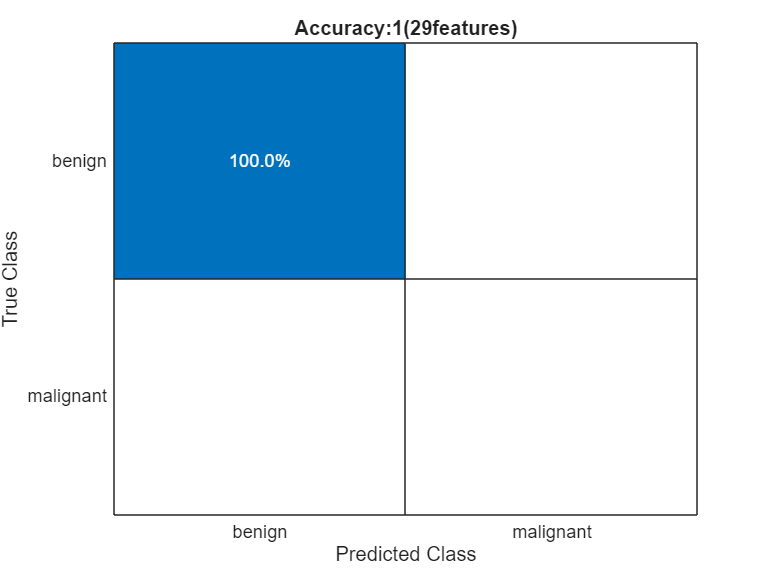

figure
confusionchart(labelsTest,predictedLabelsTest,'Normalization','row-normalized') % Normalization ="Total-normalized"
title("Accuracy:"+num2str(accuracy,3)+"("+nnz(selectedFeatures)+"features)")

**SINGLE-IMAGE CLASSIFICATION**

totalTime=0;
nIms=1;
for ii=1:nIms
    disp(ii+"of"+nIms)
    testIndex=randi([1,numel(imageImds.Files)]);
    testImage=readimage(imageImds,testIndex);
    %
    tic;
    img=readimage(imageImds,testIndex);
    img=im2gray(img);
    img=cat(3,img,zeros([size(img) 2],class(img)));
    volGeometry=medicalref3d(size(img));
    data=medicalVolume(img,volGeometry);
    data.Voxels=squeeze(data.Voxels);

    masking=readimage(maskImds,testIndex);
    masking=im2uint8(masking);
    masking=cat(3,masking,zeros([size(masking) 2],class(masking)));
    volGeometry=medicalref3d(size(masking));
    roiData=medicalVolume(masking,volGeometry);
    roiData.Voxels=squeeze(roiData.Voxels);

    R=radiomics(data,roiData);
    thisImageFeatures=[];
    if ismember("shape",string(includedFeatures))
        S=shapeFeatures(R,SubType="2D");
        S=removevars(S,"LabelID");
        thisImageFeatures=[thisImageFeatures,S];
    end
    if ismember("intensity",string(includedFeatures))
        I=intensityFeatures(R,SubType="2D");
        I=removevars(I,"LabelID");
        thisImageFeatures=[thisImageFeatures,I];
    end
    if ismember("texture",string(includedFeatures))
        T=textureFeatures(R,SubType="2D");
        I=removevars(T,"LabelID");
        thisImageFeatures=[thisImageFeatures,T];
    end
    thisImageFeatures=thisImageFeatures(:,selectedFeatures);
    %predictedLabelsTest=predict(Mdl,table2array(thisImageFeatures));
    totalTime=totalTime+toc;
end

1of1


Error using classreg.learning.internal.numPredictorsCheck (line 29)
X data must have 26 column(s).

Error in classreg.learning.classif.CompactClassificationECOC/predict (

tAverage=totalTime/nIms
figure
imshow(testImage)
t=title("Image"+testIndex+":Actual="+string(labels(testIndex))+";Predicted="+string(predictedLabelsTest));
if labels(testIndex)==predictedLabelsTest
    t.Color=[0 0.7 0];
else
    t.color=[0 0.7 0];
end

**WHAT IF YOU WANT TO  PENALIZE FALSE NEGATIVES (FOR INSTANCES)?**

% Misclassification cost, specified as a square matrix or structure array.
% If you specify a square matrix Cost and the true class of an observation
% is i, then Cost(i,j) is the cost of classifying a point into class j.
% That is, rows correspond to the true classes, and columns correspond to
% the predicted classes.

%defaultCostMatrix = [0 1; 1 0];

falseNegativeWeight =480 
newCostMatrix = [0 1; falseNegativeWeight 0]
modelNew = model;
modelNew.Cost = newCostMatrix;
predictedLabelsTestNew = predict(modelNew, radiomicsFeaturesTest);
accuracy = 1 - loss(modelNew, radiomicsFeaturesTest, labelsTest, "LossFun", "classiferror");

figure
confusionchart(labelsTest, predictedLabelsTestNew) %, Normalization = "total-normalized"
%confusionchart(labelsTest, predictedLabelsTestNew, Normalization = "total-normalized")%
title("Accuracy:"+num2str(accuracy,3)+"("+nnz(selectedFeatures)+"features)")

**EXPLORE INACCURACIES**

% AT COMMAND LINE:
badInds = find(labelsTest = predictedLabelsTestNew);
badImgs = subset(imageImds, badInds);
figure;
tl = tiledlayout("flow", TileSpacing = "tight", Padding = "tight");
title(tl, "Inaccuracies", FontSize = 18)
for ii = numel(badInds):-1:1
    ax(ii) = nexttile(tl);
    imshow(readimage(badImgs, ii))
    t = title(string(predictedLabelsTestNew(badInds(ii))), ...
        Color = "r");
    if strcmp(string(predictedLabelsTestNew(badInds(ii))), "benign")
        set(t, FontSize = 14, BackgroundColor = 0.7*[1 1 1])
    end
end
expandAxes(ax)

%

% We have declared function name pareSelction in another file 